% Util Functions
addpath(genpath('.\My5300Tools'));
addpath(genpath('.\Basic5300Tools'));

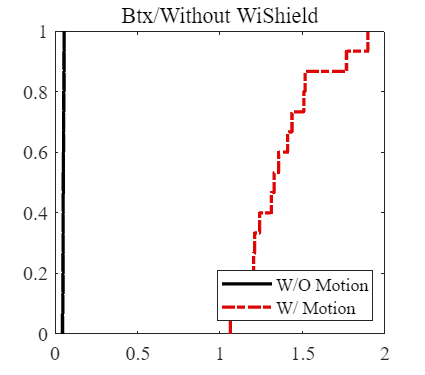

% Fig 10(a) CDF Max Var without WiShield
pre = "./Data/MotionDetection/DRandFDR/";
Tx = "Btx/";
Ox = "noOx/";
file_pre = pre+Tx+Ox;
NBatches = 15;

antennaID = 1;
type = "amplitude";

VarienceWindowTime = 1; % s
VarienceWindowSize = round( (VarienceWindowTime / 0.01) );

motion_data = [];
still_data = [];

for batch_i = 1:NBatches
    file = file_pre+batch_i;
    data = GenDataFromCSITrace(file, antennaID, type);
    data = GetNewACSIVarienceIndicator(data, VarienceWindowSize);
    still_data = [still_data max(data)];
    
    file = file_pre+batch_i+"_";
    data = GenDataFromCSITrace(file, antennaID, type);
    data = GetNewACSIVarienceIndicator(data, VarienceWindowSize);
    motion_data = [motion_data max(data)];
end

[h, ] = cdfplot(still_data);
X_still = h.XData(2:end-1);
Y_still = h.YData(2:end-1);
close(gcf)

[h, ] = cdfplot(motion_data);
X_motion = h.XData(2:end-1);
Y_motion = h.YData(2:end-1);
close(gcf)

figure
plot(X_still, Y_still, "LineWidth", 2, "Color", 'black');
hold on;
plot(X_motion, Y_motion, "LineWidth", 2, "Color", [0.8745 0.0235 0.0235], 'LineStyle', "-.");
hold off;
legend("W/O Motion", "W/ Motion", "Location", "southeast");
title(Tx+"Without WiShield")
set(gca,'FontName','Times New Roman','FontSize',12)
set(gcf,'position',[1000,500,340, 300]);

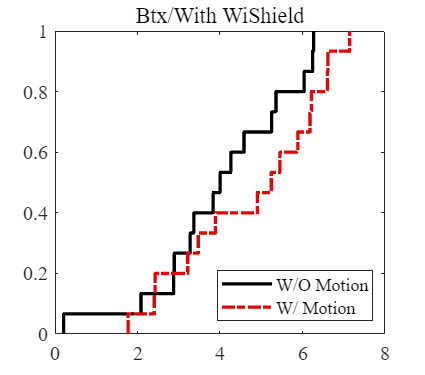

% Fig 10(b) CDF Max Var with WiShield
pre = "./Data/MotionDetection/DRandFDR/";
Tx = "Btx/";
Ox = "Ox/";
file_pre = pre+Tx+Ox;
NBatches = 15;

antennaID = 1;
type = "amplitude";

VarienceWindowTime = 1; % s
VarienceWindowSize = round( (VarienceWindowTime / 0.01) );

motion_data = [];
still_data = [];

for batch_i = 1:NBatches
    file = file_pre+batch_i;
    data = GenDataFromCSITrace(file, antennaID, type);
    data = GetNewACSIVarienceIndicator(data, VarienceWindowSize);
    still_data = [still_data max(data)];
    
    file = file_pre+batch_i+"_";
    data = GenDataFromCSITrace(file, antennaID, type);
    data = GetNewACSIVarienceIndicator(data, VarienceWindowSize);
    motion_data = [motion_data max(data)];
end

[h, ] = cdfplot(still_data);
X_still = h.XData(2:end-1);
Y_still = h.YData(2:end-1);
close(gcf)

[h, ] = cdfplot(motion_data);
X_motion = h.XData(2:end-1);
Y_motion = h.YData(2:end-1);
close(gcf)

figure
plot(X_still, Y_still, "LineWidth", 2, "Color", 'black');
hold on;
plot(X_motion, Y_motion, "LineWidth", 2, "Color", [0.8745 0.0235 0.0235], 'LineStyle', "-.");
hold off;
legend("W/O Motion", "W/ Motion", "Location", "southeast");
title(Tx+"With WiShield")
set(gca,'FontName','Times New Roman','FontSize',12)
set(gcf,'position',[1000,500,340, 300]);